**Forward Difference Approximation Derivative. **

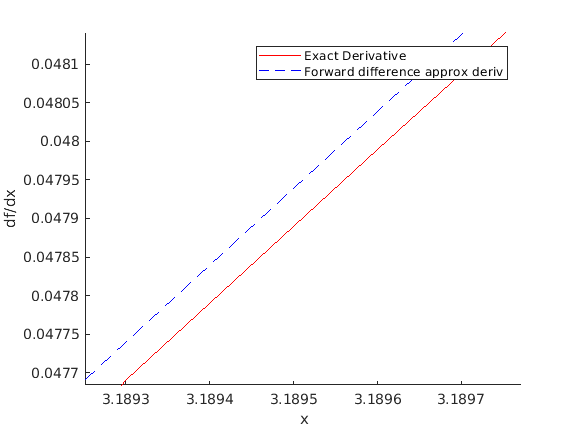

close all; clear all; clc; 


% Set up the list of equally spaced x-values
h = 0.0001; % set the separation between xs
xs = 0 : h : 4; 

f = cos(xs);
fderiv = -sin(xs); % true exact value

% Forward difference approximation: 
% f'(xn) = (f(x_n+1) - f(xn))/ (x_n+1 - xn)

% f(2) - f(1), f(3) - f(2) ...
% len = 1 less than f
f_forward = (f(2:end) - f(1:end - 1)) / h ; 

% Plot
figure(1); clf; hold on 
plot(xs, fderiv, 'r')
plot(xs(1:end-1), f_forward, 'b--')
xlabel('x')
ylabel('df/dx')
legend('Exact Derivative', 'Forward difference approx deriv')


% note that discrepancy is due to h-size. When we
% decrease the h-size, the approximation gets more
% accurate. 

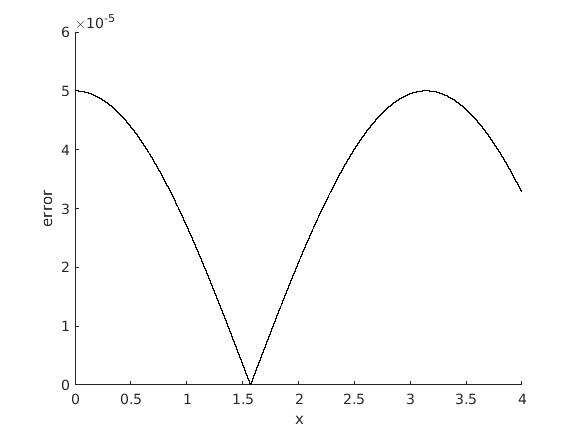

f_error = abs(fderiv(1:end-1) - f_forward);

figure(2); clf; hold on
plot(xs(1:end-1), f_error, 'k')
xlabel('x')
ylabel('error')


% maximum error is 5 * 10^-3 when h = 0.01
% maximum error is 5 * 10^-5 when h = 0.0001
% (error has dropped by 2 orders of magnitude)